# Interlocked sensor analysis

clear all
close all


## load and plot data



data=load('PressCurr.txt')

data = 1.0e+04 *

    0.0000    0.0000    0.0378
    0.0000    0.0000    0.0909
    0.0000    0.0000    0.1550
    0.0000    0.0000    0.2291
    0.0000    0.0000    0.3202
    0.0000    0.0000    0.4205
    0.0000    0.0000    0.5322
    0.0000    0.0000    0.6523
    0.0000    0.0000    0.7779
    0.0000    0.0000    0.9109


data1=load('Contact.txt')

data1 = 1.0e-06 *

    0.0167    0.0000
    0.0333    0.0000
    0.0500    0.0000
    0.0667    0.0000
    0.0833    0.0000
    0.1000    0.0000
    0.1167    0.0000
    0.1333    0.0000
    0.1500    0.0000
    0.1667    0.0000


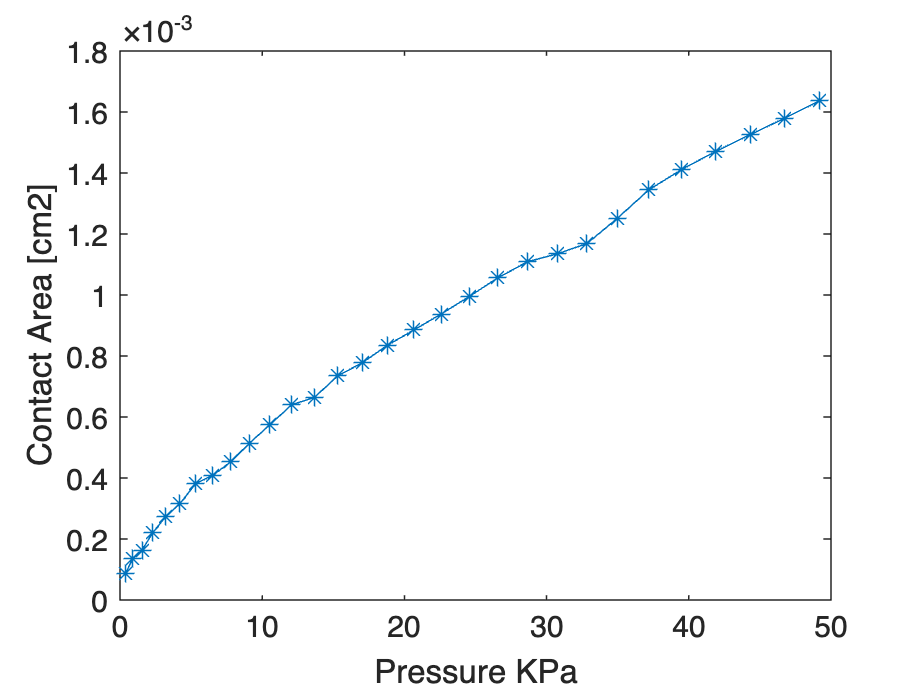

Iout=data(:,2); %sensor current A
Res=(1./Iout); %Sensor resistance in Ohm
Press=data(:,3); %Pressure in N/m2 (Pa)
ContactA=data1(:,2)*1e4 ; %contact area in m^2

figure 
plot( Press/1000, ContactA*1e4,'-*');
xlabel('Pressure KPa')
ylabel('Contact Area [cm2]')

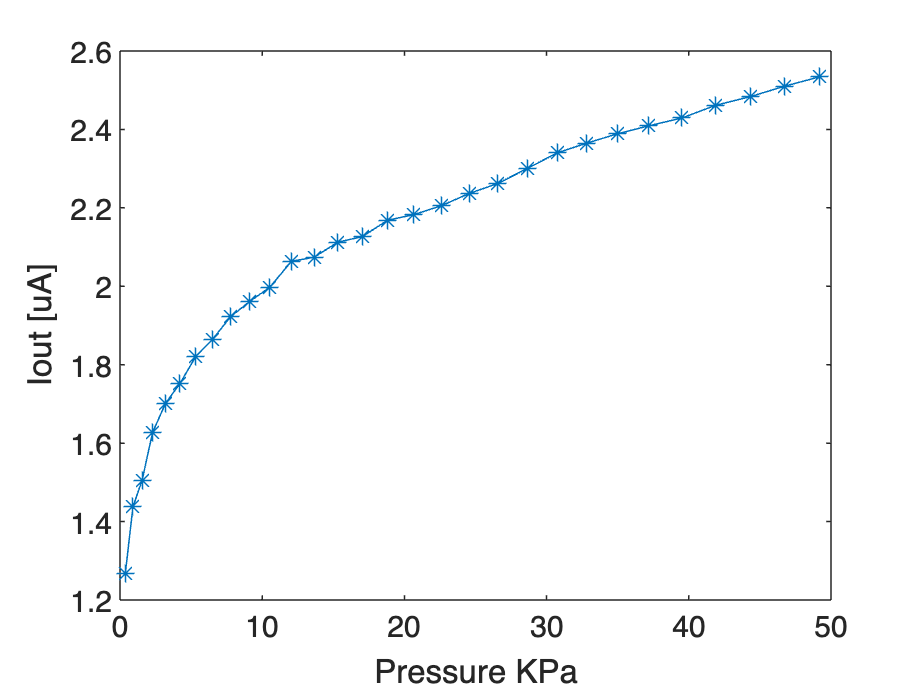



figure 
plot( Press/1000, Iout*1e6,'-*');
xlabel('Pressure KPa')
ylabel('Iout [uA]')

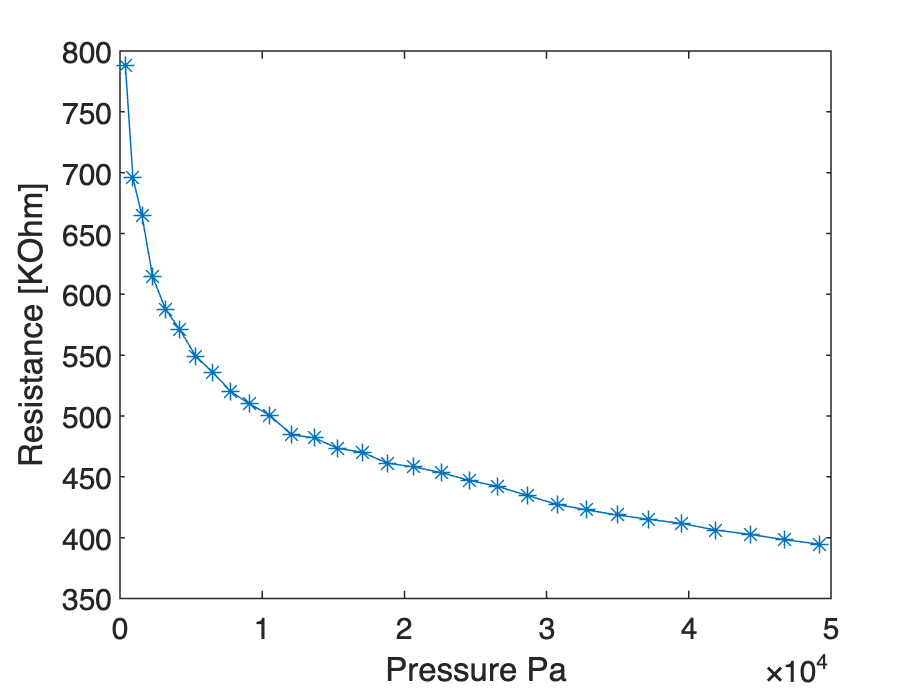


figure 
plot(Press,Res/1000,'-*')
xlabel('Pressure Pa')
ylabel('Resistance [KOhm]')